clc;clear;close all;

## 读入数据

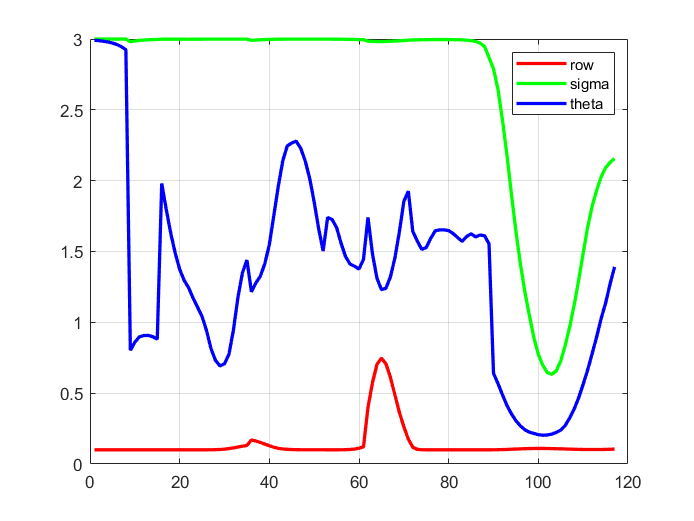

METHOD = ["PPO"];
figure();
for i = 1:size(METHOD,2)
    method = METHOD(i);
    filename = 'actionTrace' + method + '.csv';
    action_trace = csvread(filename);
    plot(1:size(action_trace,1),action_trace(:,1),"LineWidth",2,"Color","r")
    hold on;
    plot(1:size(action_trace,1),action_trace(:,2),"LineWidth",2,"Color","g")
    plot(1:size(action_trace,1),action_trace(:,3),"LineWidth",2,"Color","b")
end
legend(["row","sigma","theta"])
grid on;